# **Second-order systems analysis**

#### Setup

% A code to quickly analyze and solve second order systems
% Created by Samuel Scott

s = tf('s');


% Plant transfer function
numerator = 1; % replace as appropriate
A = 1;   % Replace coefficients as appropriate
B = 1;
C = 1;
denominator = ( (A)*s^2 + (B)*s + (C) ); 
G = numerator / denominator

G =
 
       1
  -----------
  s^2 + s + 1
 
Continuous-time transfer function.



#### Open loop control

#### 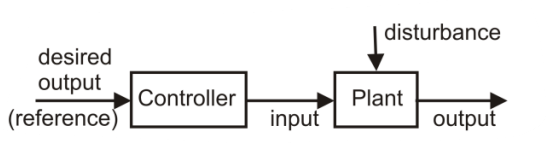

% Open loop control analysis
fprintf("\n\nOpen Loop control:\n-------------------------------------------------");



Open Loop control:
-------------------------------------------------

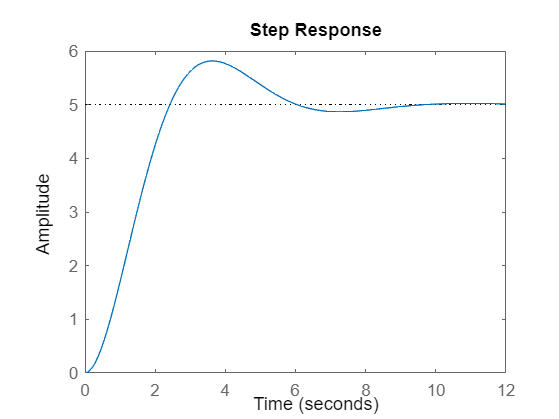



% Controller
openLoopController = 1; % change as appropriate

oLT = openLoopController*G; % open loop transfer function

% Step response
stepMagnitude = 5;
openLoopStep_oLT = step(oLT*stepMagnitude);
step(oLT*stepMagnitude)

openLoopStepInfo_oLT = stepinfo(oLT*stepMagnitude)

openLoopStepInfo_oLT = struct with fields:
         RiseTime: 1.6390
    TransientTime: 8.0759
     SettlingTime: 8.0759
      SettlingMin: 4.6576
      SettlingMax: 5.8146
        Overshoot: 16.2929
       Undershoot: 0
             Peak: 5.8146
         PeakTime: 3.5920



[openLoopPoles, openLoopZeros] = pzmap(oLT*stepMagnitude)

openLoopPoles =   -0.5000 + 0.8660i
  -0.5000 - 0.8660i



openLoopZeros =

  0×1 empty double column vector




% A general second order system



% Frequency response






#### Closed loop control